# rDCM connectivity matrix pruning

In this notebook we'll describe the procedure first described in Frässle et al. (2018) that prunes a fully connected network to estimate only certain connectivity parameters.

Based on see Eq. 7 in Frässle et al. 2018 pruning happens with the addition of a feature selector Z matrix placed between the design matrix X (that contains the other nodes activity and convolved inputs in the frequency domain) and the parameters vector $\theta$. Z is a diagonal matrix with binary indicators that effectively "selects" columns from X. If the diagonal in Z corresponding to a column in X is 0 then no parameter is estimated for that feature (or $\theta$=0). Different from the ridge regression optimization is run over not just the connectivity parameters $\theta$ and measurement noise $\tau$ but also the feature selector matrix Z.

Z is determined by its diagonal $\zeta$'s which come from a binomial distribution with probability $p$. This $p$ is what is updated in each variational iteration to update Z.

`tapas_rdcm_sparse.m` is provided with a prior $p_0$ that is used in a binomial distribution to determine the initial Z matrix. It then loops through each region and estimates parameters for both connectivity and task involvement for each region depending on the "feature selectivity" vector determined by p0 for that region (detailed below).

In their simulations Frässle et al. found that the recovered parameters especially for connectivity depended on how close the prior p0 was to the true sparseness of the simulation. So in their estimations `tapas_rdcm_sparse.m` is run for a number of prior values determined in `tapas_rdcm_estimate.m`.

Here I provide a brief overview of the procedures in each step and then simulate some data to explore the effects of the prior on the estimated connectivity matrix.

## Order of operation

`tapas_rdcm_estimate.m` --> `tapas_rdcm_sparse.m` --> `tapas_rdcm_get_prior_all.m` --> `tapas_rdcm_spm_dcm_fmri_priors.m `

### tapas_rdcm_estimate.m

- For the sparse method iterates over (19) p0_temp values ranging from 0.05 to 0.95 and calls `tapas_rdcm_sparse.m` for each p0_temp value.

- Saves output for each p0_temp value in `output_all`

- Selects the cell from `output_all` that has the highest Free Energy (empirical Bayes)

- So what does p0_temp change in `tapas_rdcm_sparse.m`?

### tapas_rdcm_sparse.m

- Loops through each node/region

- 100 iterations for each node

- p0_temp determines p0 vector ("informativeness of feature", "sparsity hyperparameter") in each of these iterations

-             p0 is the prior probability for the Bernoulli distribution that sets the binary indicators (zetas $\zeta$) for the existance of a connection

- E.g. for our simulations for node 1 it is [1 p0_temp p0_temp 1]. Its length is determined by the number of parameters that will be estimated for that regions. In this case the first three values are the connectivity values (A(1,:)) and the last value is the input effect (C(1)). The first value is the self-connection, second and third are connections **incoming** **from **(verified in Frässle et al. 2018, p 508) other regions to this region.

- Select estimates with the highest Free Energy from all iterations for each region (**for the given p0_temp value**)

-             For each node there are 100 iterations/initilizations that have up to 500 convergence rounds

-             So should there be a lot or little variability in the parameter estimates depending on iteration?

% Plot distribution of mean connectivity, covariance and estimates depending on iteration

### tapars_rdcm_get_prior_all.m

- resets pE.A from `tapas_rdcm_spm_dcm_fmri_priors.m` to 0's except for inhibitory self connections

- m0 = [pE.A pE.B pE.C]; i.e. all prior expectations

- **inverts** all values in pC resulting from `tapas_rdcm_spm_dcm_fmri_priors.m `(l0 is $\Sigma_0^{-1}$)

- l0 = [pC.A pC.B pC.C]; i.e. all prior covariances

- sets noise shape and rate parameters priors to 2 and 1 respectively 

### tapas_rdcm_spm_dcm_fmri_priors.m 

- pE describes prior expected values and pC prior covariances

- **for A: prior on self-connectivity is inhibitory (diag of pE.A < 0) and narrow (diag of pC.A is small)**

- **for other connections in A the priors are closer to 0 and wide**

- pE and pC are set to 0 and 1 respectively for B, C, D matrices

Set up simulation parameters

rngSeed = rng();
cmap = mycmap();
stim_options = get_default_stim_options();
type = 'r'; % setting to 'r' instead of 's' until bug is fixed

% specify number of simulations
num_sims = 12;

## Effect of p0 prior on pruning

Code replicated from `tapas_rdcm_estimate.m`.

Simulate 10 subjects and invert them using tapas_rdcm_sparse.m plugging in 19 different priors for p0 (feature selector).

% result array for all p0
options.p0_all = 0.05:0.05:0.95;
output_all  = cell(num_sims,length(options.p0_all));
F_all       = NaN(num_sims,length(options.p0_all));

for sim_counter = 1:num_sims

    [DCM, options] = make_DEM_demo_induced_fmri(stim_options);
    DCM = rmfield(DCM,'U');
    
    % check for endogenous DCMs, with no exogenous driving effects
    if ( ~isfield(DCM,'c') || isempty(DCM.c) || ~isfield(DCM,'U') || isempty(DCM.U.u) || strcmp(DCM.U.name{1},'null') )
        
        % specify empty driving input
        DCM.U.u     = zeros(size(DCM.Y.y,1)*16, 1);
        DCM.U.name  = {'null'};
        DCM.U.dt    = DCM.Y.dt/16;
        
        % specify effective connectivity matrices
        DCM.b = zeros(DCM.n, DCM.n, size(DCM.U.u,2));
        DCM.c = zeros(DCM.n, size(DCM.U.u,2));
        DCM.d = zeros(DCM.n, DCM.n, 0);
        
    end
    
    
    % create the options file
    options = tapas_rdcm_set_options(DCM, options, type);
    
    
    % create the regressors
    [X, Y, DCM, args] = tapas_rdcm_create_regressors(DCM, options);
    
       
    % specify the default grid for optimizing sparsity hyperparameter p0
    if ( ~isfield(options,'p0_all') )
        options.p0_all = 0.05:0.05:0.95;
    end

    % iterate over p0 values
    for p0_counter = 1:length(options.p0_all)
        
        % specify p0
        args.p0_temp = options.p0_all(p0_counter);
        
        % output progress of regions
        if ( length(options.p0_all) ~= 1 ), args.verbose = 0; else, args.verbose = 1; end
        
        % rDCM (with sparsity constraints)
        output_temp	= tapas_rdcm_sparse(DCM, X, Y, args);
        output_all{sim_counter, p0_counter} = output_temp{1};
        
        % get the negative free energy
        F_all(sim_counter, p0_counter) = output_all{sim_counter, p0_counter}.logF;
        
    end
end

How do the estimated pruned connectivity matrices look like different values of p0 compared to the true connectivity matrix (averaging across 10 subjects)?

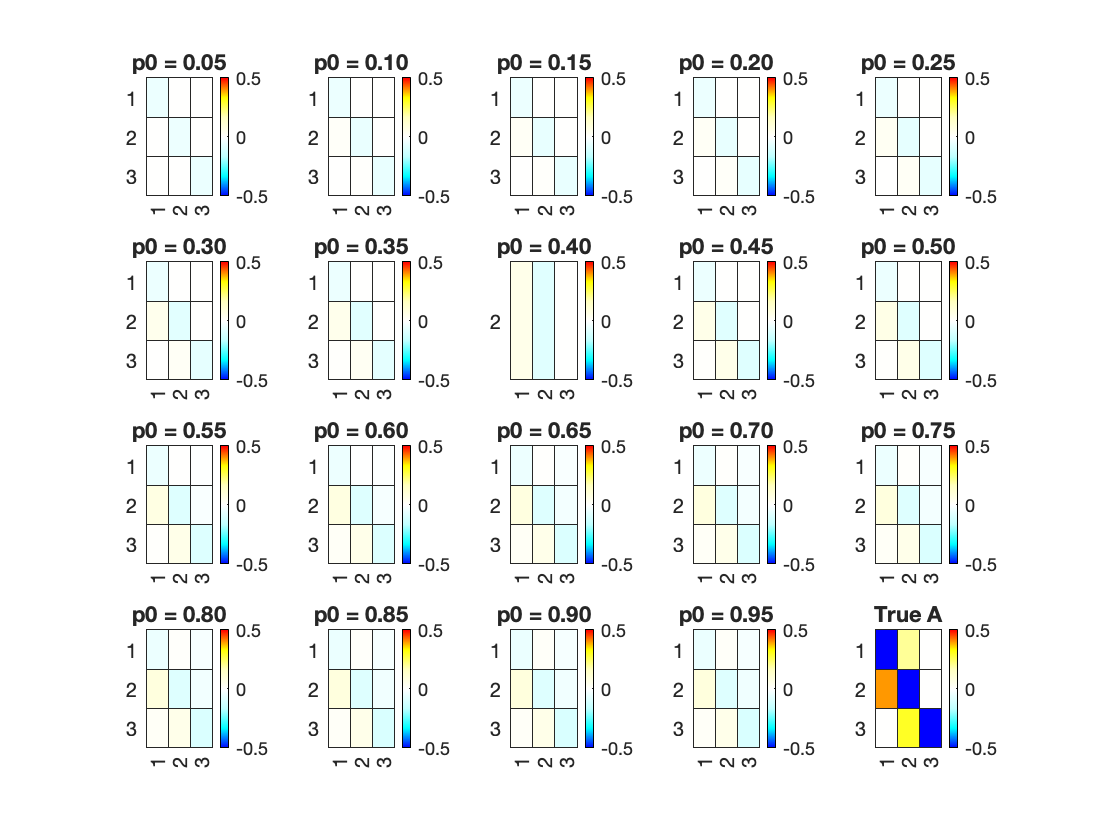

for i = 1:length(output_all)
    subplot(4, 5, i)
    cur_as = cellfun(@(c) {c.Ep.A}, output_all(:,i));
    mean_a = mean(cat(3, cur_as{:}), 3);
    h = heatmap(mean_a);
    h.CellLabelColor = 'none';
    h.Colormap = cmap;
    h.ColorLimits = [-0.5 0.5];
    title(sprintf("p0 = %.02f", output_all{1, i}.priors.p0));
end

subplot(4, 5, 20)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A");

What is the sparsity of the true network? (What proportion of the values in the true connectivity matrix are 0?)

sum(reshape(DCM.Tp.A, 1, DCM.n*DCM.n) == 0)/(DCM.n*DCM.n)

ans = 0.3333

Is the estimated connectivity most similar to the true connectivity where p0 is the closes to the true network sparsity (i.e 0.3 - 0.4)? Doesn't look like it looking at the average connectivity matrices above but looking at model evidence possibly.

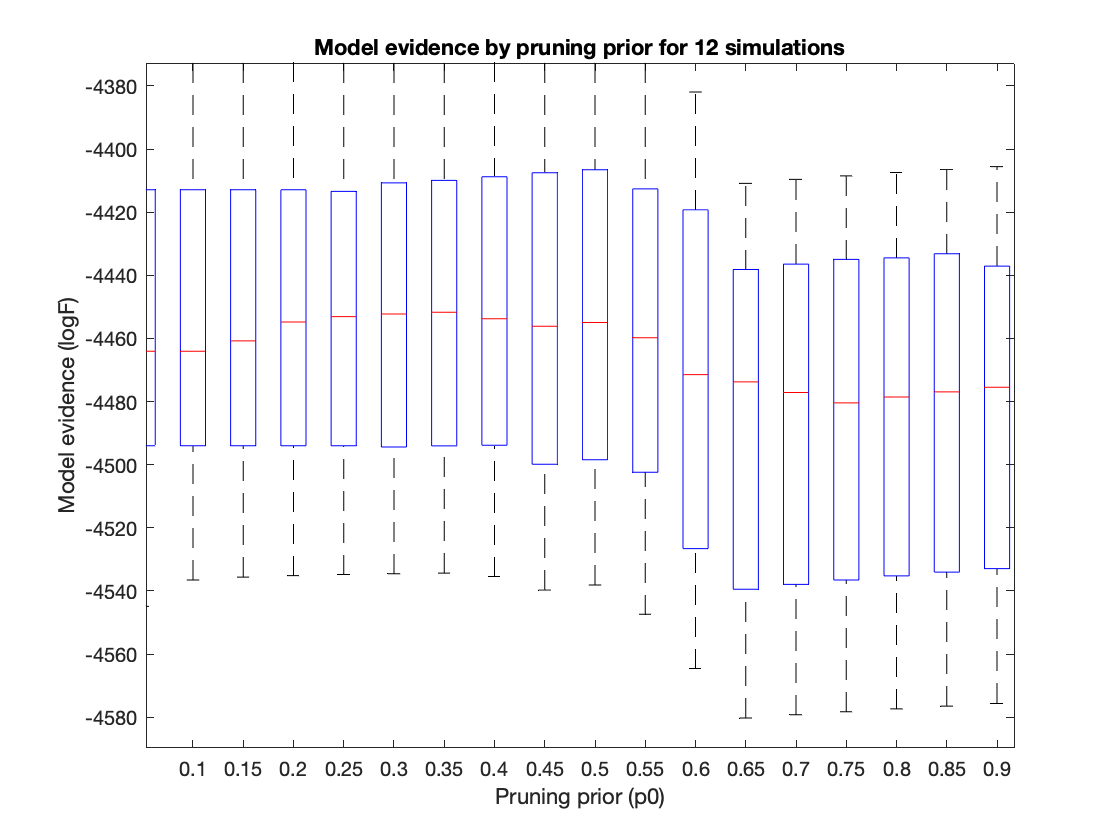

tmp = zeros(size(output_all,1)*size(output_all,2), 2);
for i = 0:(length(output_all)-1)
    tmp(i*num_sims+1:(i+1)*num_sims,1) = cell2mat(cellfun(@(c) {c.priors.p0}, output_all(:,i+1)));
    tmp(i*num_sims+1:(i+1)*num_sims,2) = cell2mat(cellfun(@(c) {c.logF}, output_all(:,i+1)));
end
clf
boxplot(tmp(:,2), tmp(:,1))
title(sprintf("Model evidence by pruning prior for %.0f simulations", num_sims))
ylabel("Model evidence (logF)")
xlabel("Pruning prior (p0)")

Of all the simulated datasets which has the highest model evidence? What is the "best" estimate for *any* subject?

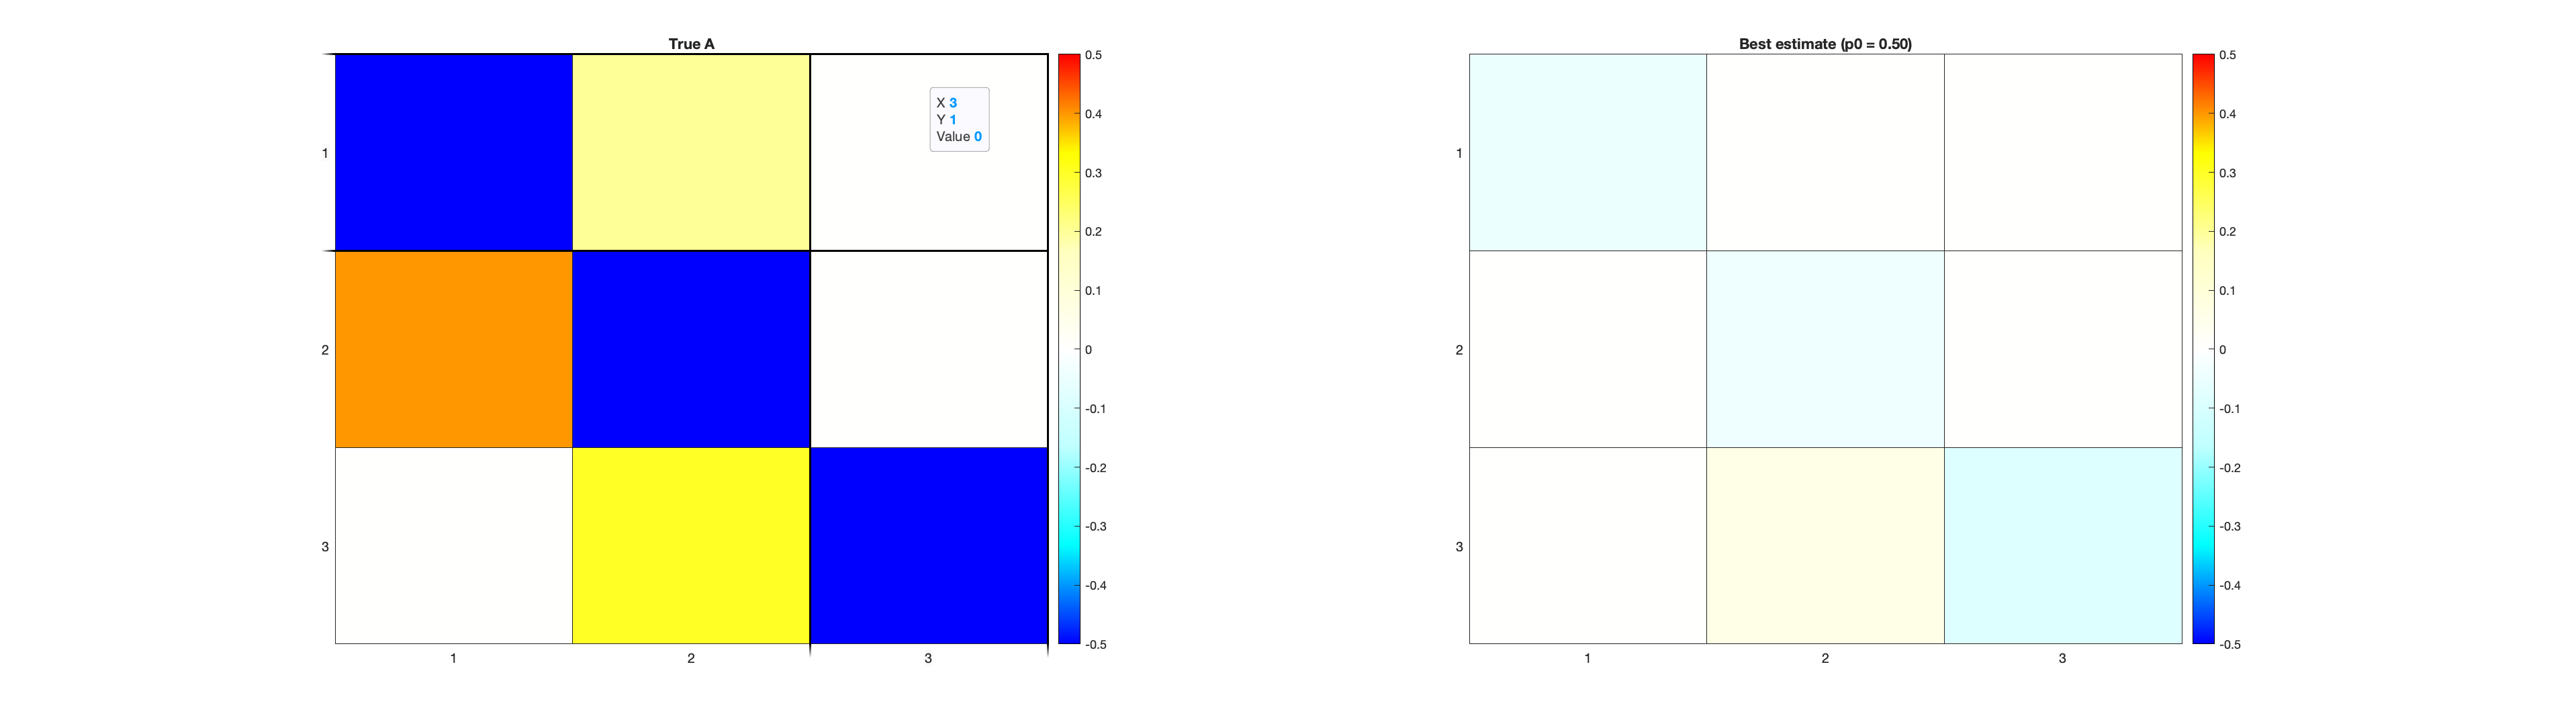

[Fmax, ind] = max(tmp(:,2));
colind = options.p0_all == tmp(ind,1);
rowind = mod(ind, num_sims);

f = figure();

subplot(1, 2, 1)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A");

subplot(1, 2, 2)
h = heatmap(output_all{rowind, colind}.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title(sprintf("Best estimate (p0 = %.02f)", output_all{rowind, colind}.priors.p0));

set(f,'Units','normalized','Position',[0 0 1 .5]); 

Is the most similar matrix the same as the one that has the highest Free Energy?

How to define similarity? RMSE

Why are the magnitudes of the connectivity estimates so small? Would they vary more if the priors for the connectivity estimates (not p0, which is the prior for whether the connection exists) were wider?

What does the predicted timeseries (**what the model is fit on is timeseries not connectivity**) look like for the best fitting parameters?